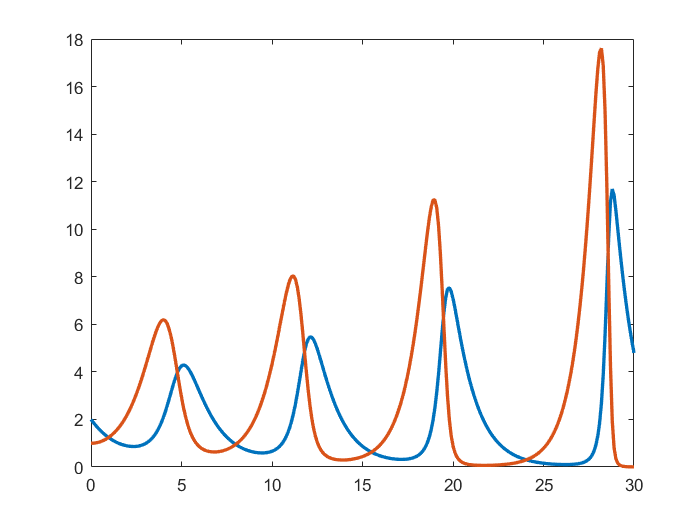

clc,clear,close all
a = 1.2; b = 0.6; c = 0.8; d = 0.3;
dy = @(x,y) [-c*y(1)+d*y(1)*y(2);
    a*y(2)-b*y(1)*y(2)];
y0 = [2;1];
x = 0:0.1:30;


y = euler(dy,y0,x);
plot(x,y(1,:),x,y(2,:),"LineWidth",2)